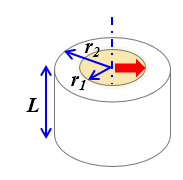    $
R=C_F \frac{1}{2 \pi k L} \ln \left(\frac{r_2}{r_1}\right)
$                $$R$ : Thermal resistance value (deg $\mathrm{C} / \mathrm{W}$ )
$k$ : Thermal conductivity of the object to be heated/cooled $(\mathrm{W} / \mathrm{m} / \mathrm{deg}$
C)
$L$ : Height of the object to be heated/cooled $(\mathrm{mm})$
$r_1$ : Inner radius of the object to be heated/cooled $(\mathrm{mm})$
$r_2$ : Outer radius of the object to be heated/cooled $(\mathrm{mm})$
$C_F$ : Correction factor (Default: 1)$

function R = calcRthRadial(C_F, k, L, outerR, innerR)
% Calculate the radial thermal resistance of a cylindrical structure.
% Parameters: C_F: Correction factor 
% k: Thermal conductivity of the material (W/m/°C) 
% L: Length of the cylinder (mm) 
% outerR: Outer radius of the cylinder (mm)
% innerR: Inner radius of the cylinder (mm) 
% Returns: R: Radial thermal resistance (°C/W)
    
    LinMeter    =mm2m(L);
    r1inMeter   =mm2m(innerR);
    r2inMeter   =mm2m(outerR);

    % Calculate the radial thermal resistance
    R = C_F * (1 / (2 * pi * k * LinMeter)) * log(r2inMeter / r1inMeter);
end
                    